グラフ : Cruise

[x,y] = meshgrid([200:5:300],[20000:1000:40000]);

%変数の値
%climb_distance用
weight = 69154.86794;
headwind = 3.41940696;
temp_difference = 9.633138618;
%descent_distance用
headwind_des = 2.429077428;
temp_difference_des = 9.561988899;
%cruise_time,fuel
headwind_cruise = -12.82750286;
temp_difference_cruise = 9.561988899;
weight_cruise = 67695.1105;
wingtip_cruise = 0.320555226;

%係数climb_distance
intercept = -581.45;
c_weight = 0.0036577;
c_climbing_speed = 0.66159;
c_cruise_altitude = 0.0096896;
c_headwind = 3.1816;
c_temp_difference = -7.3901;
c_weight2headwind = -0.0000200;
c_climbing_speed2headwind = -0.0038753;
c_climbing_speed2temp_difference = 0.022309;
c_cruise_altitude2headwind = -0.0000403;
c_cruise_altitude2temp_difference = 0.00010272;
%係数descent_distance
intercept_des = -36.614;
c_cruise_altitude_des = 0.0055504;
c_headwind_des = 0.28211;
c_temp_difference_des = -1.0476;
c_cruise_altitude2headwind_des = -0.0000216;
%係数cruise_distance
c_climbing_speed_cr = 0.22546;
c_climbing_distance_cr = -0.38017;
c_descent_distance_cr = -1.8041;
c_climbing_speed2climbing_distance_cr = -0.0024113;
c_climbing_speed2descent_distance_cr = 0.00334;
intercept_cr = 664.54;
%係数cruise_time
intercept_cruise_t = -262.94;
c_headwind_cruise_t = -7.4017;
c_distance_cruise_t = 5.8726;
c_temp_difference_cruise_t = 12.018;
c_headwind2distance_cruise_t = 0.043329;
c_distance2temp_difference_cruise_t = -0.049373;
%係数cruise_fuel
intercept_cruise_f = 557.07;
c_weight_cruise_f = -0.012065;
c_wingtip_cruise_f = -404.31;
c_cruise_altitude_f = -0.035726;
c_headwind_cruise_f = -6.623;
c_distance_cruise_f = 8.2013;
c_weight2wingtip_cruise_f = 0.0064968;
c_weight2cruise_altitude_cruise_f = 0.000000708;
c_weight2headwind_cruise_f = 0.00010846;
c_wingtip2distance_cruise_f = -0.34165;
c_cruise_altitude2distance_cruise_f = -0.0000678;
c_headwind2distance_cruise_f = 0.0071336;

%climb_distance計算
climb_distance = intercept ...
    + c_weight .* weight ...
    + c_headwind .* headwind ...
    + c_climbing_speed .* x ...
    + c_temp_difference .* temp_difference ...
    + c_cruise_altitude .* y ...
    + c_weight2headwind .* weight .* headwind ...
    + c_climbing_speed2headwind .* x .* headwind ...
    + c_climbing_speed2temp_difference .* x .* temp_difference ...
    + c_cruise_altitude2headwind .* y .* headwind ...
    + c_cruise_altitude2temp_difference .* y .* temp_difference

climb_distance =   -10.0671   -5.7509   -1.4347    2.8816    7.1978   11.5140   15.8302   20.1464   24.4627   28.7789   33.0951   37.4113   41.7276   46.0438   50.3600   54.6762   58.9924   63.3087   67.6249   71.9411   76.2573
    0.4742    4.7904    9.1066   13.4229   17.7391   22.0553   26.3715   30.6878   35.0040   39.3202   43.6364   47.9526   52.2689   56.5851   60.9013   65.2175   69.5338   73.8500   78.1662   82.4824   86.7986
   11.0155   15.3317   19.6480   23.9642   28.2804   32.5966   36.9128   41.2291   45.5453   49.8615   54.1777   58.4940   62.8102   67.1264   71.4426   75.7588   80.0751   84.3913   88.7075   93.0237   97.3400
   21.5568   25.8730   30.1893   34.5055   38.8217   43.1379   47.4542   51.7704   56.0866   60.4028   64.7191   69.0353   73.3515   77.6677   81.9839   86.3002   90.6164   94.9326   99.2488  103.5651  107.8813
   32.0981   36.4144   40.7306   45.0468   49.3630   53.6793   57.9955   62.3117   66.6279   70.9441   75.2604   79.5766   83.8928   88.209


descent_distance = intercept_des ...
    + c_temp_difference_des .* temp_difference_des ...
    + c_cruise_altitude_des .* y ...
    + c_headwind_des .* headwind_des ...
    + c_cruise_altitude2headwind_des .* y .* headwind_des

descent_distance =    64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128   64.0128
   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107   69.5107
   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086   75.0086
   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066   80.5066
   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0045   86.0


cruise_distance = intercept_cr ...
    + c_climbing_speed_cr .* x ...
    + c_climbing_distance_cr .* climb_distance ...
    + c_descent_distance_cr .* descent_distance ...
    + c_climbing_speed2climbing_distance_cr .* x .* climb_distance ...
    + c_climbing_speed2descent_distance_cr .* x .* descent_distance

cruise_distance =   645.5893  644.1325  642.5716  640.9067  639.1377  637.2646  635.2874  633.2061  631.0208  628.7314  626.3379  623.8403  621.2387  618.5330  615.7232  612.8093  609.7914  606.6694  603.4433  600.1131  596.6788
  630.2519  628.7599  627.1637  625.4635  623.6592  621.7508  619.7384  617.6218  615.4012  613.0766  610.6478  608.1150  605.4780  602.7371  599.8920  596.9428  593.8896  590.7323  587.4709  584.1055  580.6360
  614.9146  613.3872  611.7558  610.0203  608.1808  606.2371  604.1894  602.0376  599.7817  597.4217  594.9577  592.3896  589.7174  586.9411  584.0608  581.0764  577.9879  574.7953  571.4986  568.0979  564.5931
  599.5772  598.0146  596.3479  594.5772  592.7023  590.7234  588.6404  586.4533  584.1621  581.7669  579.2676  576.6642  573.9567  571.1452  568.2296  565.2099  562.0861  558.8582  555.5263  552.0903  548.5502
  584.2399  582.6420  580.9400  579.1340  577.2239  575.2097  573.0914  570.8690  568.5426  566.1121  563.5775  560.9388  558.1961  555.34


cruise_time = intercept_cruise_t ...
    + c_headwind_cruise_t .* headwind_cruise ...
    + c_distance_cruise_t .* cruise_distance ...
    + c_temp_difference_cruise_t .* temp_difference_cruise ...
    + c_headwind2distance_cruise_t .* headwind_cruise .* cruise_distance ...
    + c_distance2temp_difference_cruise_t .* cruise_distance .* temp_difference_cruise

cruise_time = 	1.0e+03 *

    3.0746    3.0675    3.0600    3.0519    3.0433    3.0343    3.0247    3.0146    3.0040    2.9929    2.9813    2.9692    2.9566    2.9435    2.9299    2.9158    2.9012    2.8860    2.8704    2.8543    2.8376
    3.0003    2.9931    2.9853    2.9771    2.9684    2.9591    2.9494    2.9391    2.9284    2.9171    2.9053    2.8931    2.8803    2.8670    2.8532    2.8389    2.8241    2.8088    2.7930    2.7767    2.7599
    2.9260    2.9186    2.9107    2.9023    2.8934    2.8840    2.8740    2.8636    2.8527    2.8412    2.8293    2.8169    2.8039    2.7905    2.7765    2.7621    2.7471    2.7316    2.7157    2.6992    2.6822
    2.8517    2.8441    2.8360    2.8275    2.8184    2.8088    2.7987    2.7881    2.7770    2.7654    2.7533    2.7407    2.7276    2.7139    2.6998    2.6852    2.6701    2.6544    2.6383    2.6216    2.6045
    2.7774    2.7696    2.7614    2.7526    2.7434    2.7336    2.7234    2.7126    2.7013    2.6896    2.6773    2.6645    2.6512


cruise_fuel = intercept_cruise_f ...
    + c_weight_cruise_f .* weight_cruise ...
    + c_wingtip_cruise_f .* wingtip_cruise ...
    + c_cruise_altitude_f .* y ...
    + c_headwind_cruise_f .* headwind_cruise ...
    + c_distance_cruise_f .* cruise_distance ...
    + c_weight2wingtip_cruise_f .* weight_cruise .* wingtip_cruise ...
    + c_weight2cruise_altitude_cruise_f .* weight_cruise .* y ...
    + c_weight2headwind_cruise_f .* weight_cruise .* headwind_cruise ...
    + c_wingtip2distance_cruise_f .* wingtip_cruise .* cruise_distance ...
    + c_cruise_altitude2distance_cruise_f .* y .* cruise_distance ...
    + c_headwind2distance_cruise_f .* headwind_cruise .* cruise_distance

cruise_fuel = 	1.0e+03 *

    4.2760    4.2663    4.2559    4.2449    4.2331    4.2207    4.2075    4.1937    4.1792    4.1640    4.1481    4.1315    4.1142    4.0962    4.0776    4.0582    4.0381    4.0174    3.9960    3.9738    3.9510
    4.1436    4.1337    4.1233    4.1121    4.1002    4.0877    4.0744    4.0605    4.0459    4.0306    4.0146    3.9980    3.9806    3.9626    3.9439    3.9245    3.9044    3.8837    3.8622    3.8401    3.8173
    4.0132    4.0033    3.9926    3.9814    3.9694    3.9567    3.9434    3.9294    3.9147    3.8994    3.8833    3.8666    3.8492    3.8311    3.8124    3.7930    3.7729    3.7521    3.7306    3.7085    3.6857
    3.8849    3.8749    3.8641    3.8527    3.8407    3.8279    3.8145    3.8004    3.7856    3.7702    3.7541    3.7374    3.7199    3.7018    3.6830    3.6636    3.6435    3.6227    3.6012    3.5791    3.5563
    3.7587    3.7486    3.7377    3.7262    3.7140    3.7012    3.6877    3.6735    3.6587    3.6432    3.6271    3.6102    3.5928

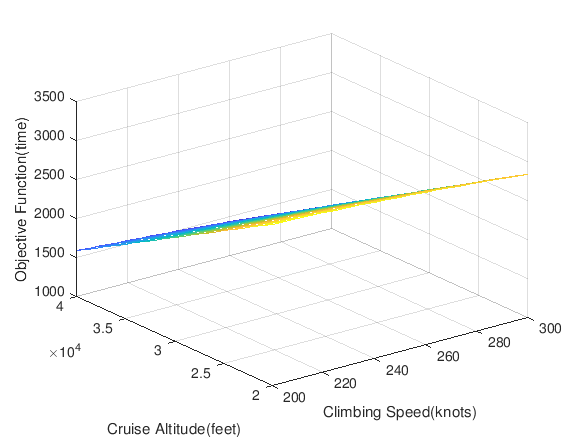

mesh(x,y,cruise_time)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(time)')

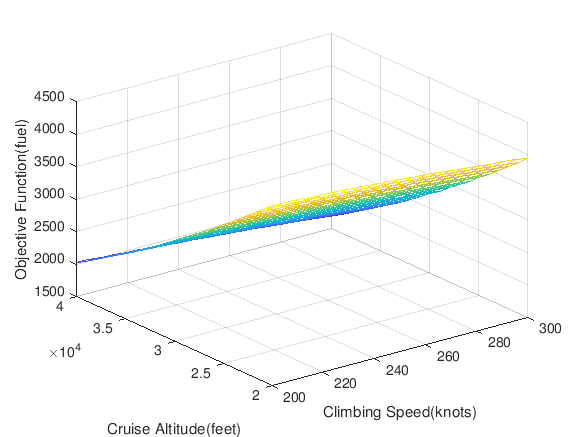

mesh(x,y,cruise_fuel)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(fuel)')

mean_time = 2013.615665

mean_time = 2.0136e+03

mean_fuel = 1787.810128

mean_fuel = 1.7878e+03

weight_time = 1.0

weight_time = 1

weight_fuel = 1.0

weight_fuel = 1

score_timefuel = weight_time .* cruise_time ./ mean_time + weight_fuel .* cruise_fuel ./ mean_fuel 

score_timefuel =     3.9187    3.9097    3.9002    3.8900    3.8792    3.8677    3.8556    3.8428    3.8295    3.8154    3.8008    3.7855    3.7696    3.7530    3.7358    3.7180    3.6995    3.6804    3.6606    3.6402    3.6192
    3.8077    3.7986    3.7889    3.7785    3.7676    3.7560    3.7437    3.7308    3.7173    3.7032    3.6884    3.6730    3.6569    3.6403    3.6230    3.6050    3.5864    3.5672    3.5474    3.5269    3.5058
    3.6979    3.6886    3.6788    3.6683    3.6571    3.6454    3.6330    3.6200    3.6064    3.5921    3.5772    3.5617    3.5455    3.5287    3.5113    3.4933    3.4746    3.4553    3.4353    3.4148    3.3936
    3.5892    3.5798    3.5698    3.5592    3.5479    3.5360    3.5235    3.5104    3.4966    3.4822    3.4672    3.4515    3.4353    3.4184    3.4009    3.3827    3.3639    3.3445    3.3245    3.3039    3.2826
    3.4817    3.4722    3.4620    3.4512    3.4398    3.4278    3.4152    3.4019    3.3880    3.3735    3.3584    3.3426    3.3262    3.309

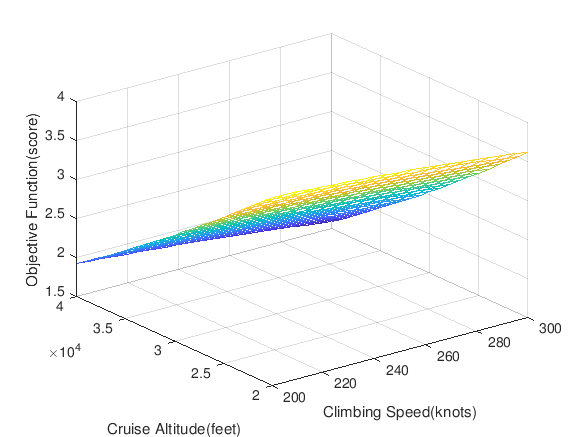

mesh(x,y,score_timefuel)
xlabel('Climbing Speed(knots)')
ylabel('Cruise Altitude(feet)')
zlabel('Objective Function(score)')